Setting Environment

Tips : to find ProjectDirectory type "**pwd**" in command Window

ProjectDirectory = "/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project"

ProjectDirectory = "/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project"

fuel = "B100";
RPM = "2500";
Torque = "160";
DataDirectory = ProjectDirectory + "/DataBase/AVLGas for four cases/";
addpath(ProjectDirectory + "/function");
path = DataDirectory + fuel + "/" + RPM + ", " + Torque + ".csv";

Data = AVLGas(path, [2, Inf]);
AmbientTemp = Data.AmbientTemperatureC(1);
AirPressure = Data.AirPressurembar;
Average = Data(end,:);
% Assuming 'Lambda' is the name of the variable you want to check for NaN
rowsWithNaN = isnan(Data.Lambda);
Data(rowsWithNaN, :) = [];
Data(end,:) = [];
Data(:, [1 3:5 end-1 end]) = []

Data = 152×14 table
    Times    N    NMax    k1m    kMax1m    COvol    COcorrectedvol    CO2vol    HCppm    HCcorrppm    Dilution    O2vol    Lambda    NOppm
    _____    _    ____    ___    ______    _____    ______________    ______    _____    _________    ________    _____    ______    _____

     0.4     0    2.8      0      0.07       0            0            7.95      11         21          1.9       9.38     1.828      670 
     0.8     0    2.8      0      0.07       0            0            7.95      11   

Varname = Data.Properties.VariableNames;
Tstart = min(Data.Times);
Tend = max(Data.Times);

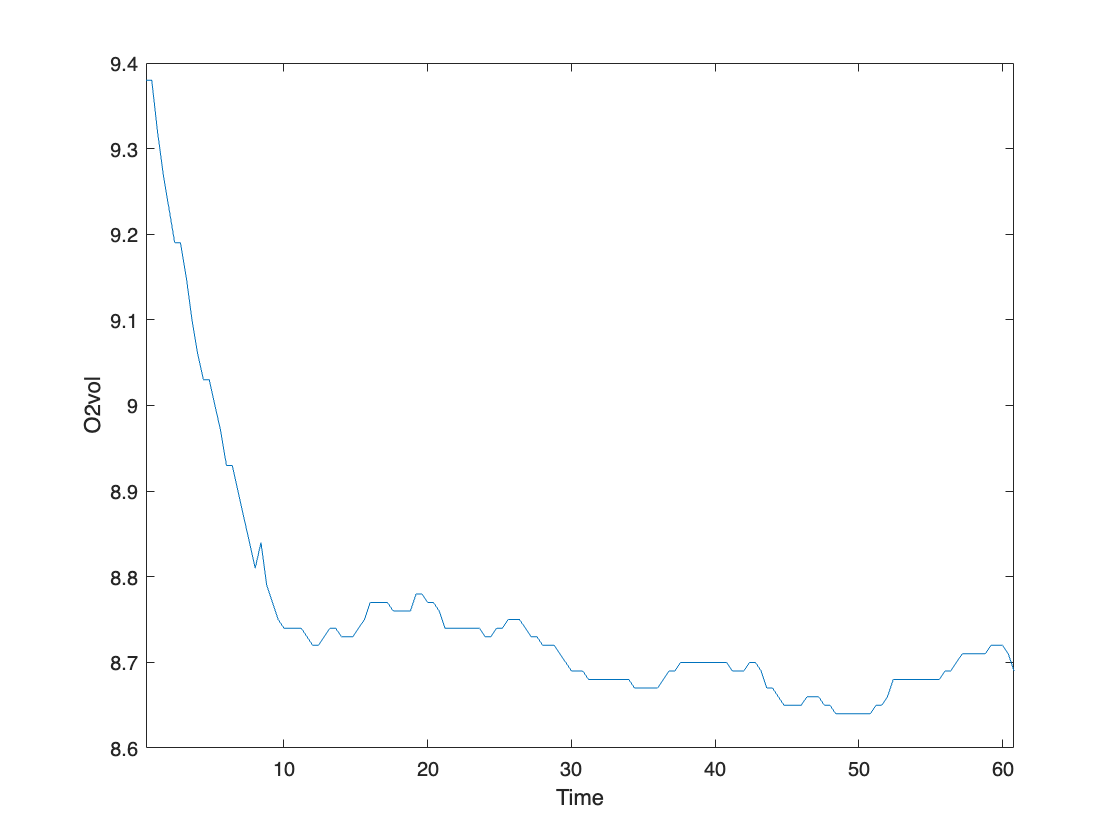

idx = 11;
plot(Data.Times, Data.(Varname{1 + idx}));
xlabel('Time');
ylabel(Varname{1 + idx});
xlim([min(Data.Times) max(Data.Times)]);
hold off

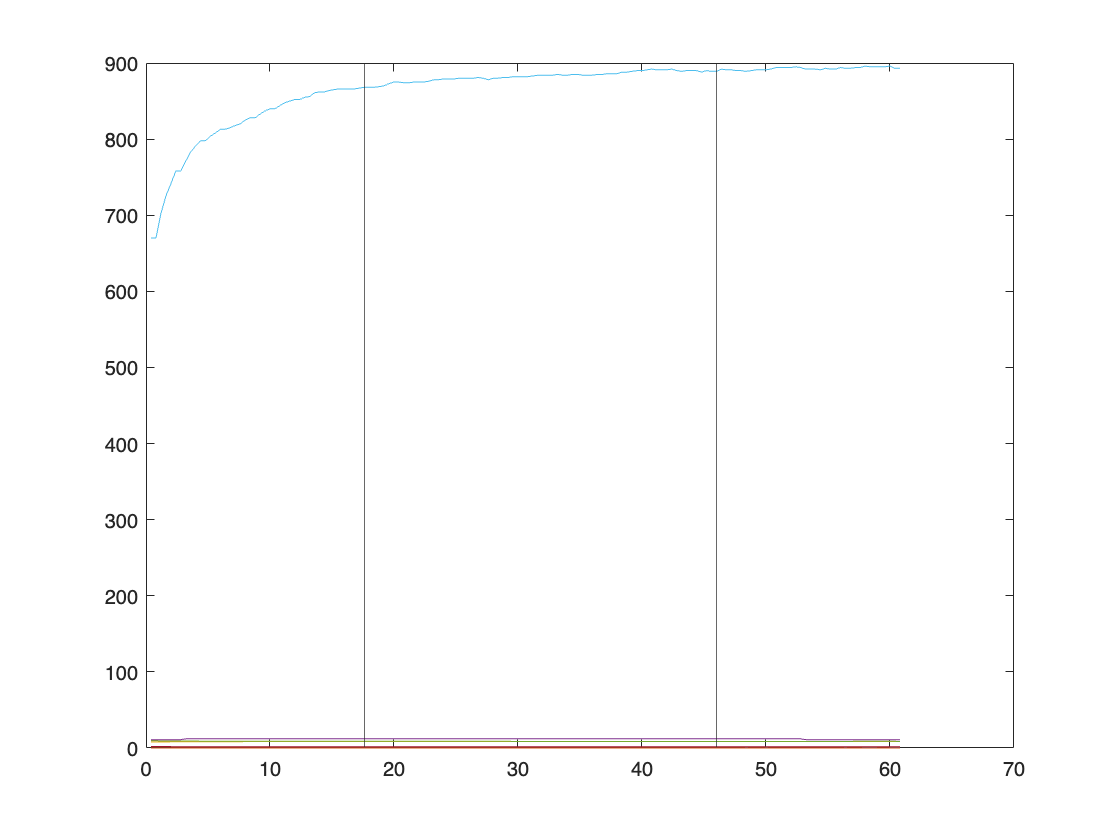


if (true)
    plot(Data.Times, Data.N);
    hold on 
end
if (true)
    plot(Data.Times, Data.COvol);
    hold on
end
if (true)
    plot(Data.Times, Data.CO2vol);
    hold on
end
if (true)
    plot(Data.Times, Data.HCppm);
    hold on
end
if (true)
    plot(Data.Times, Data.O2vol);
    hold on
end
if (true)
    plot(Data.Times, Data.NOppm);
    hold on
end
if (true)
    plot(Data.Times, Data.Lambda);
end
range_min =17.6;
range_max =46;
xline(range_max);
xline(range_min);
hold off


avg_N = ft_average([Data.Times,Data.N],[range_min range_max])

avg_N = 0.0083

avg_COvol = ft_average([Data.Times,Data.COvol],[range_min range_max])

avg_COvol = 0

avg_CO2vol = ft_average([Data.Times,Data.CO2vol],[range_min range_max])

avg_CO2vol = 8.4922

avg_HCppm = ft_average([Data.Times,Data.HCppm],[range_min range_max])

avg_HCppm = 12

avg_O2vol = ft_average([Data.Times,Data.O2vol],[range_min range_max])

avg_O2vol = 8.7086

avg_NOppm = ft_average([Data.Times,Data.NOppm],[range_min range_max])

avg_NOppm = 882.4583

avg_Lambda = ft_average([Data.Times,Data.Lambda],[range_min range_max])

avg_Lambda = 1.7195